# Demostration of the MouseMazePlot Class

*Matthias Wolff*

BTU Cottbus-Senftenberg

try
  addFockBoxToPath;
catch
  error('Change to examples folder to run this live script!');
end

Create a maze with walls:

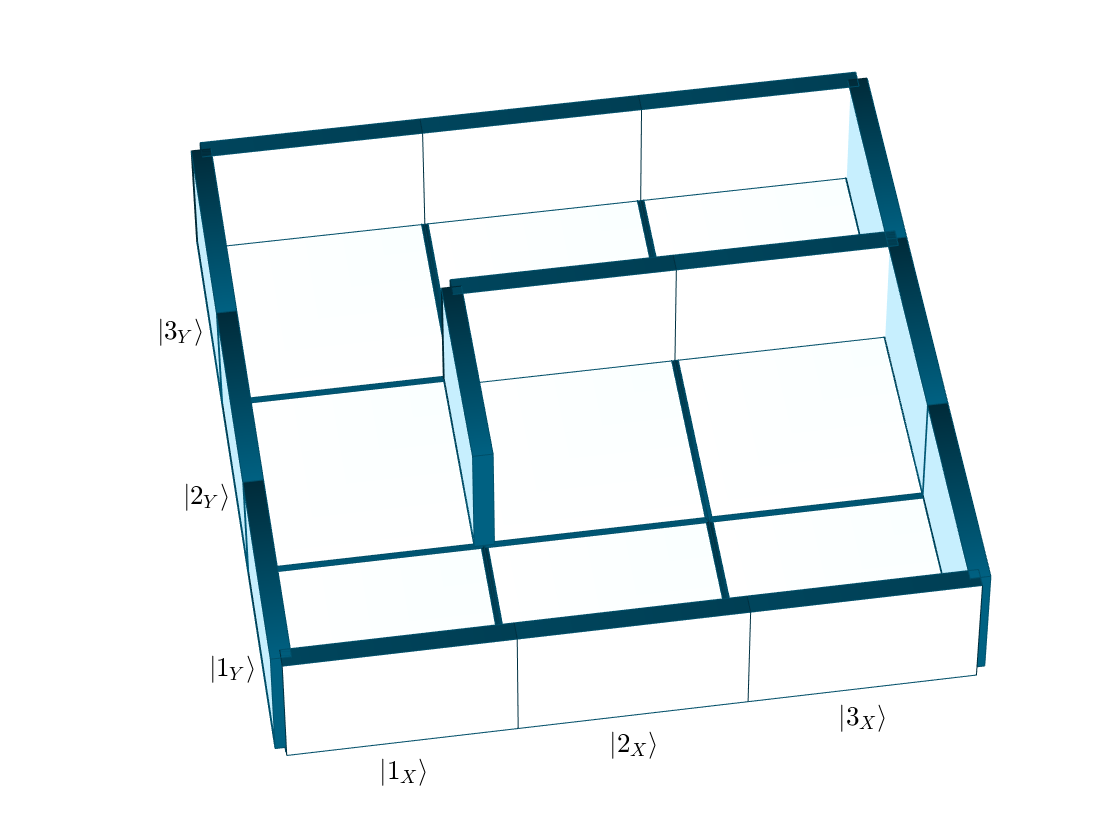

mmp = MouseMazePlot([3 3]);
mmp.setCamPos(-1,-18,23);
for i=1:mmp.getDim(1)
  mmp.addWall(i,1,'S');
  mmp.addWall(i,mmp.getDim(2),'N');
end
for i=1:mmp.getDim(2)
  mmp.addWall(1,i,'W');
  mmp.addWall(mmp.getDim(1),i,'E');
end
mmp.addWall(2,2,'W');
mmp.addWall(2,2,'N');
mmp.addWall(3,2,'N');

Add mouse and a bit of cheese:

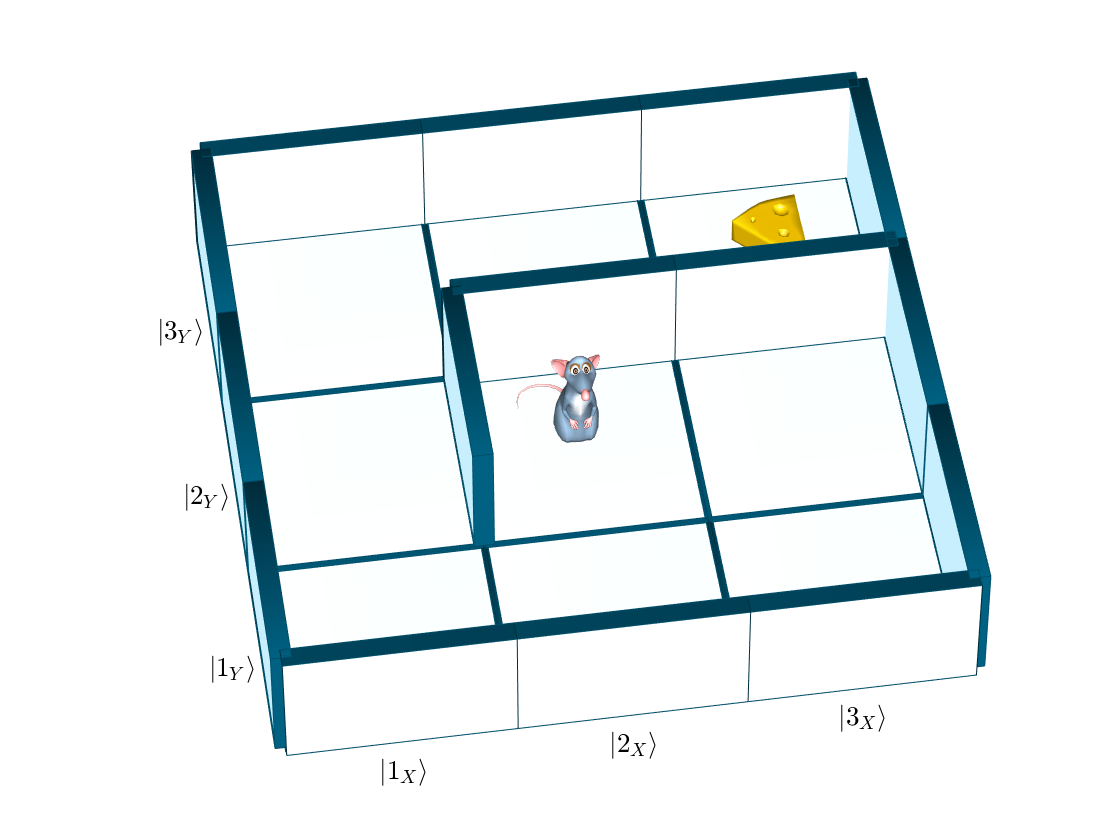

mmp.addMouse(2,2,1,180);
mmp.addCheese(3,3);

Add semi-transparent mice:

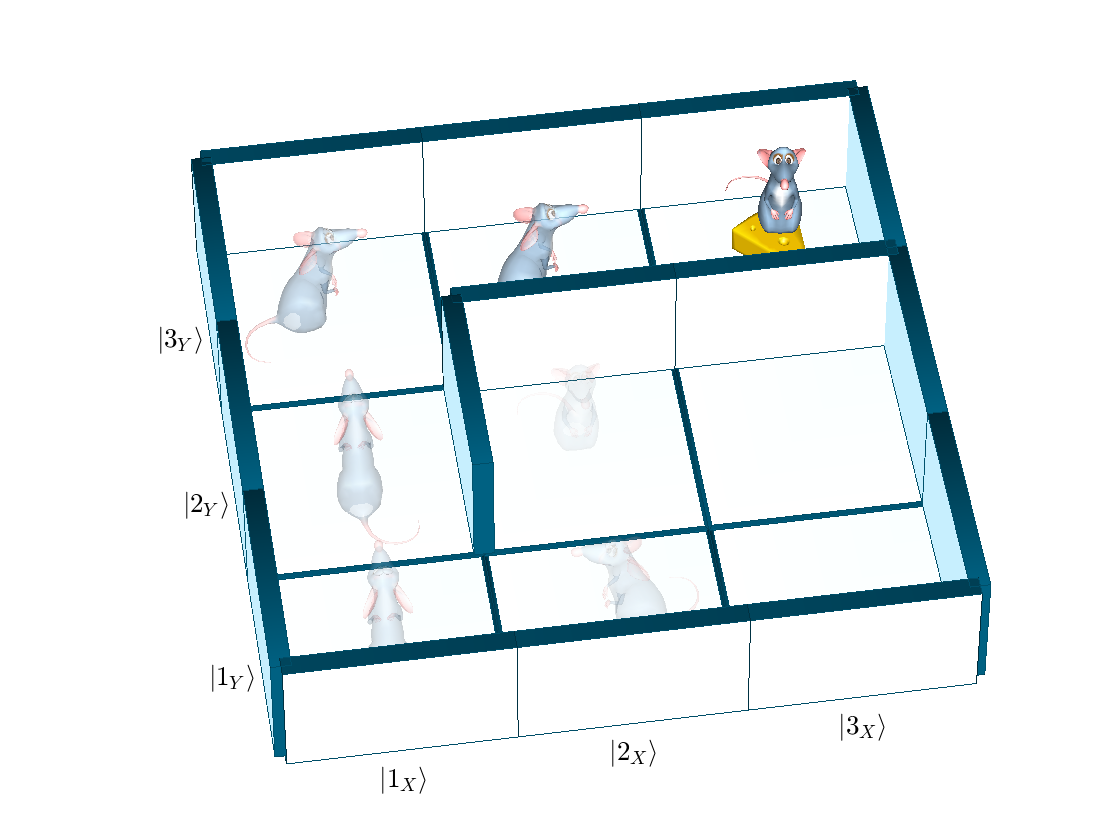

mmp.addMouse(2,2,0.05,180);
mmp.addMouse(2,1,0.1,-90);
mmp.addMouse(1,1,0.15,0);
mmp.addMouse(1,2,0.2,0);
mmp.addMouse(1,3,0.3,90);
mmp.addMouse(2,3,0.5,90);
mmp.addMouse(3,3);

Note: Transparency is indended to visualize probabilities. It is supported for all maze objects, i.e. mice, cheese bits, floor tiles, and walls.

Colorize floor tiles:

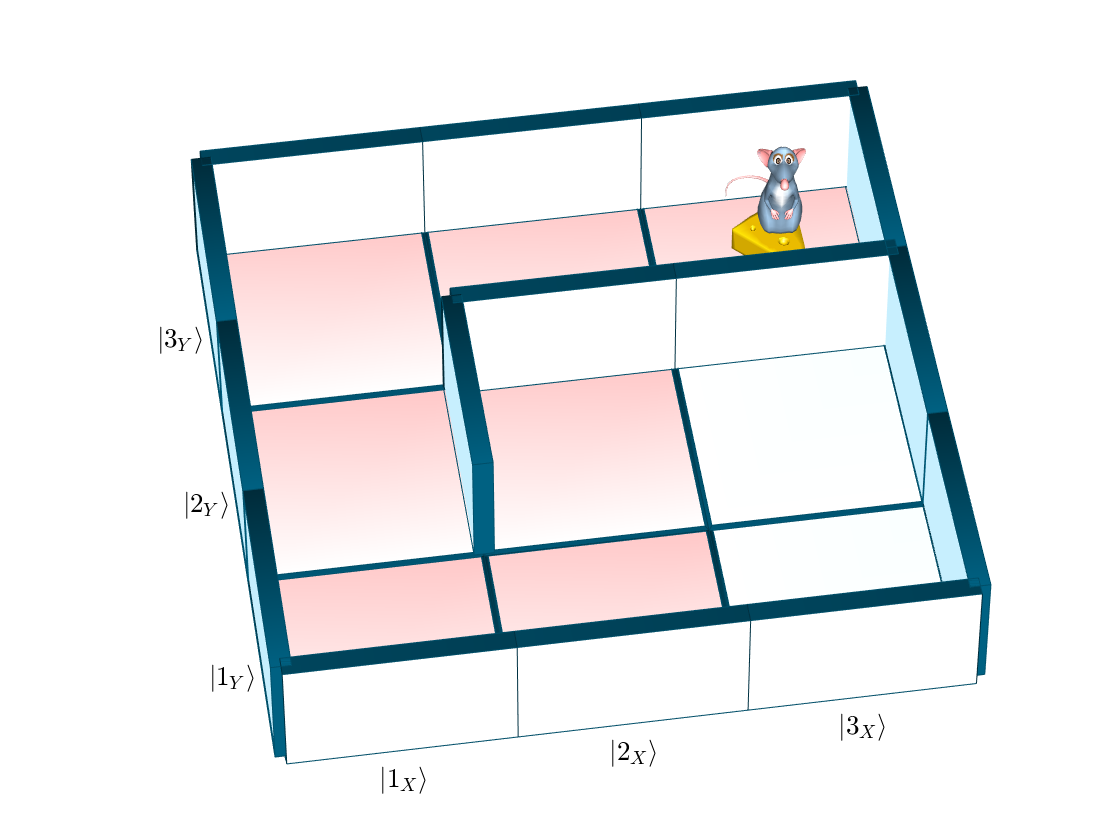

% Remove all mice with probability <1
mice = mmp.getAllMice();
for i=1:length(mice)
  if mice(i).p<1
    mmp.removeMouse(mice(i).x,mice(i).y);
  end
end

% Colorize some floor tiles
mmp.addFloorTile(2,2,1,[0.9 0.6 0.6]);
mmp.addFloorTile(2,1,1,[0.9 0.6 0.6]);
mmp.addFloorTile(1,1,1,[0.9 0.6 0.6]);
mmp.addFloorTile(1,2,1,[0.9 0.6 0.6]);
mmp.addFloorTile(1,3,1,[0.9 0.6 0.6]);
mmp.addFloorTile(2,3,1,[0.9 0.6 0.6]);
mmp.addFloorTile(3,3,1,[0.9 0.6 0.6]);

Note: Coloring is supported for floor tiles and walls.

Remove walls and enlarge maze:

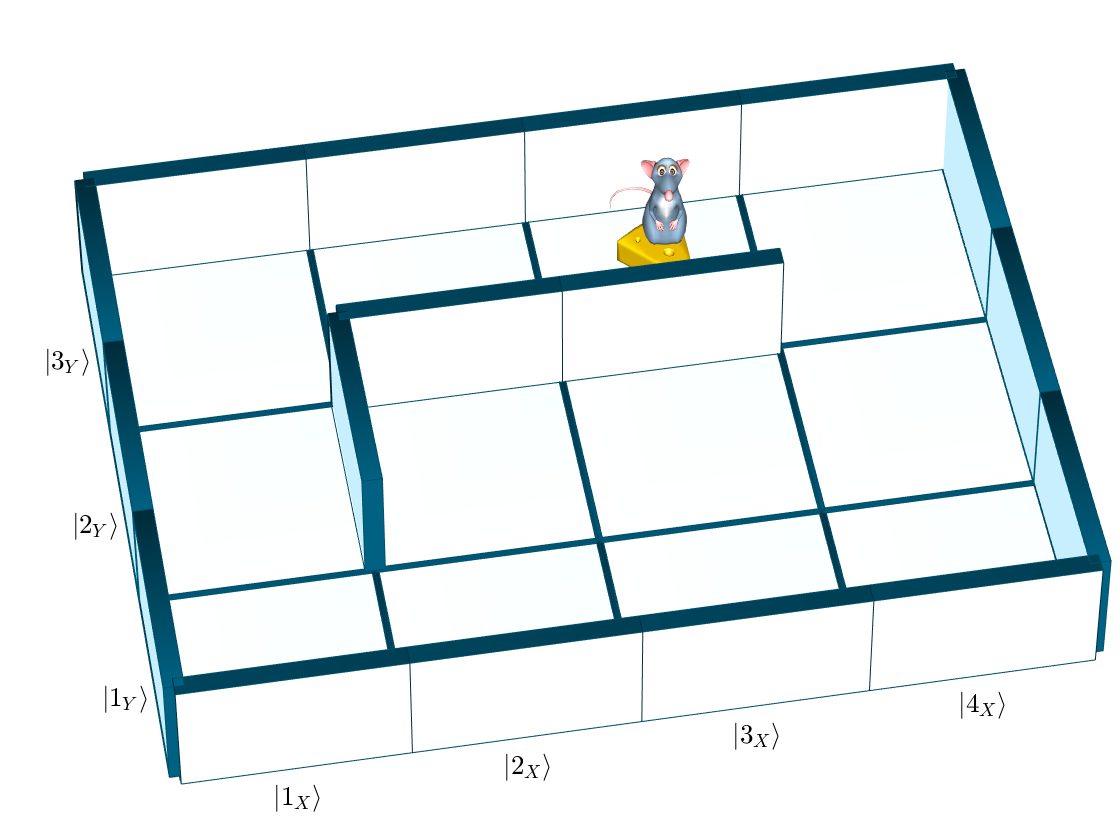

% Reset floor tile colors
tiles = mmp.getAllFloorTiles();
for i=1:length(tiles)
  mmp.addFloorTile(tiles(i).x,tiles(i).y);
end

% Remove eastern boundary walls, enlarge maze, and add boundary walls
mmp.removeWall(3,1,'E');
mmp.removeWall(3,2,'E');
mmp.removeWall(3,3,'E');
mmp.addFloorTile(4,1); mmp.addWall(4,1,'E'); mmp.addWall(4,1,'S');
mmp.addFloorTile(4,2); mmp.addWall(4,2,'E');
mmp.addFloorTile(4,3); mmp.addWall(4,3,'E'); mmp.addWall(4,3,'N');

Make all existing walls semi-transparent and red:

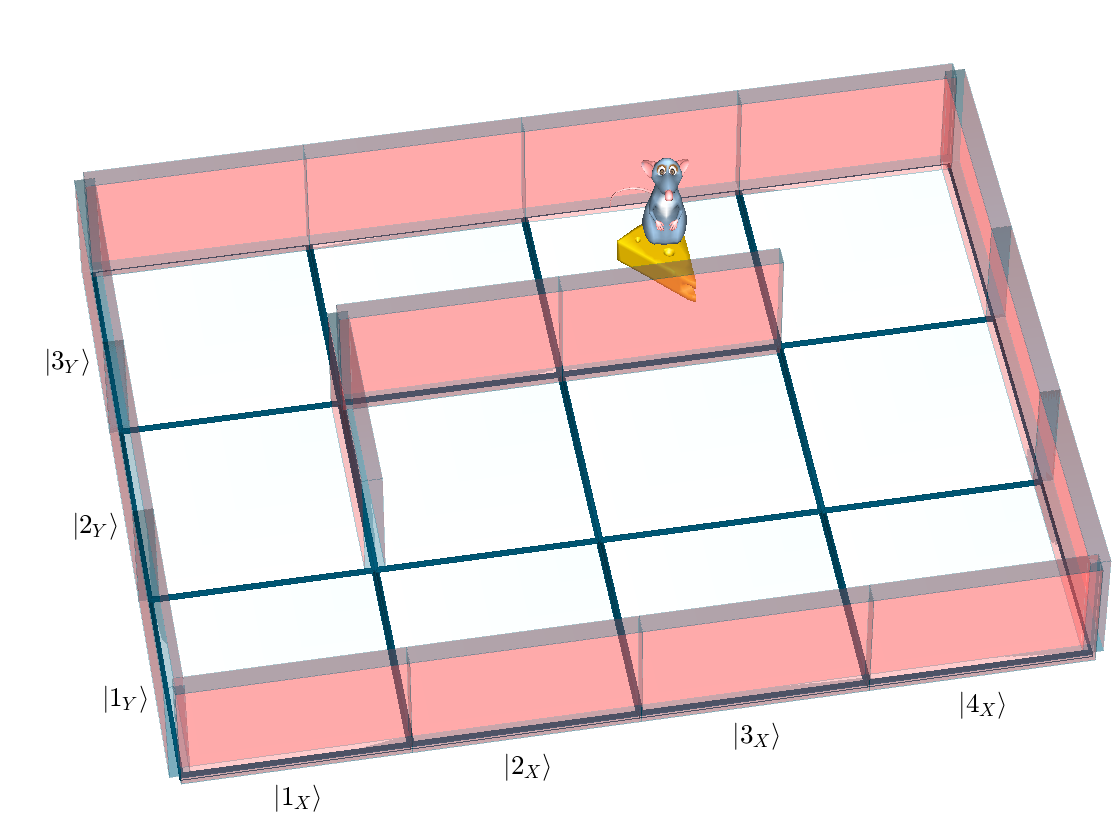

walls = mmp.getAllWalls();
for i=1:length(walls)
  mmp.addWall(walls(i).x,walls(i).y,walls(i).d,0.3,[0.9 0.2 0.2]);
end

And, finally, there is water for the mouse and also a cat...

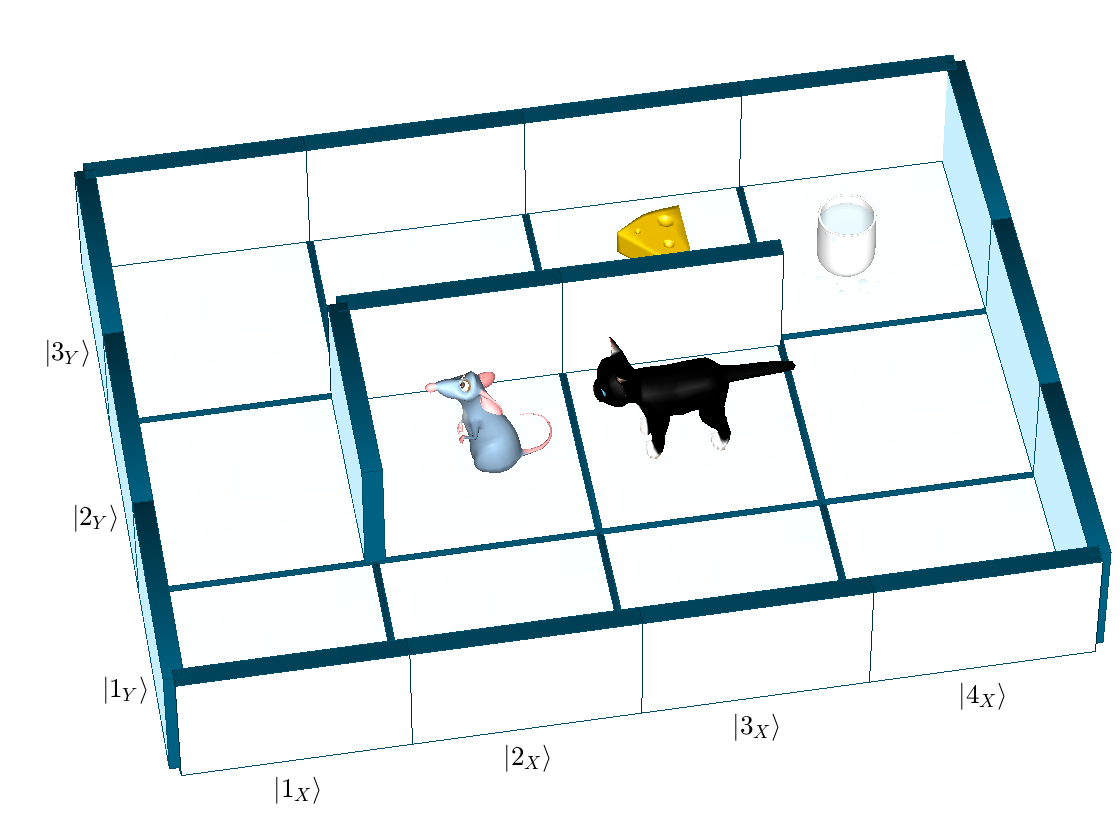

% Reset walls
walls = mmp.getAllWalls();
for i=1:length(walls)
  mmp.addWall(walls(i).x,walls(i).y,walls(i).d);
end

% Add water and cat, move mouse
mmp.addWater(4,3);
mmp.addCat(3,2,1,-90);
mmp.moveMouse(2,2,-90);

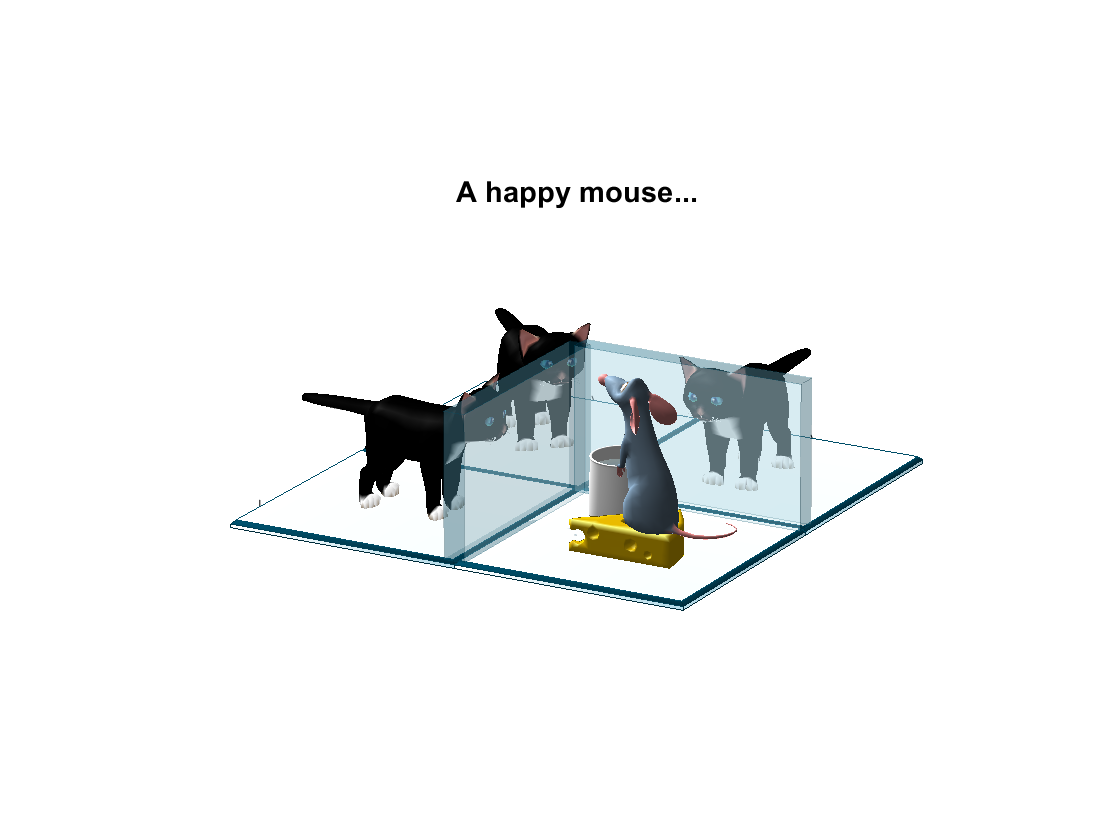

% A happy mouse...
figure;
mmp=MouseMazePlot([2 2]);
mmp.addCheese(2,2);
mmp.addWater(2,2);
mmp.addWall(2,2,'W',0.3);
mmp.addWall(2,2,'S',0.3);
mmp.addMouse(2,2);
mmp.addCat(2,1);
mmp.addCat(1,1,1,45);
mmp.addCat(1,2,1,90);
mmp.setCamPos(35,20,13);
title('A happy mouse...');